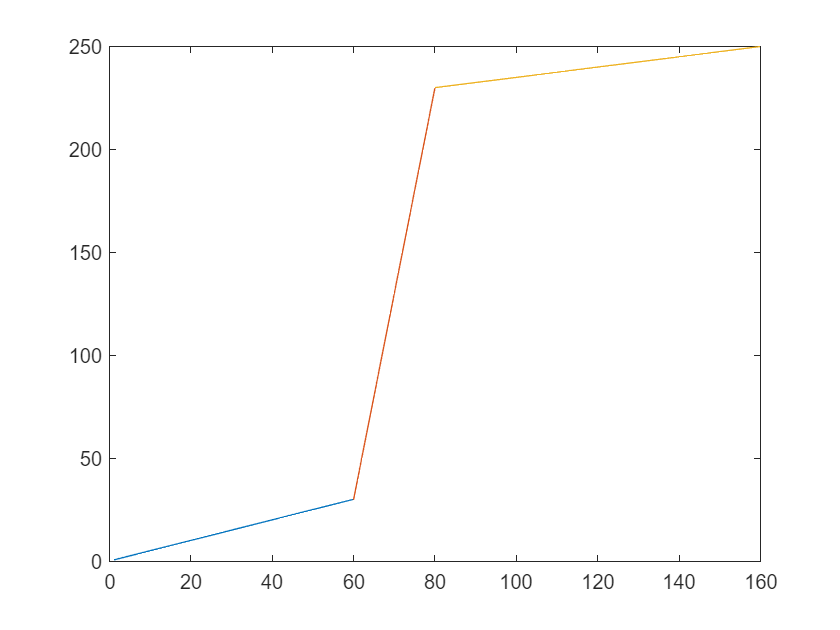

clear
x=[20 20 20 20 20 20 20 40;160 60 60 60 60 60 60 40;160 60 70 70 70 70 60 40;160 60 70 80 80 70 60 40;160 60 70 80 80 70 60 40;160 60 70 70 70 70 60 40;160 60 60 60 60 60 60 60;160 120 120 120 120 120 120 120];
[m,n]=size(x);

for i=1:60
    lut(i)=0.5*i;
end
for i=60:80
    lut(i)=10*(i-57);
end
for i=80:160
    lut(i)=0.25*i+210;
end

for i=1:m
    for j=1:n
        y(i,j)=lut(x(i,j));
    end
end

t=1:60;
t1=60:80;
t2=80:160;
figure
plot(t,lut(t),t1,lut(t1),t2,lut(t2));

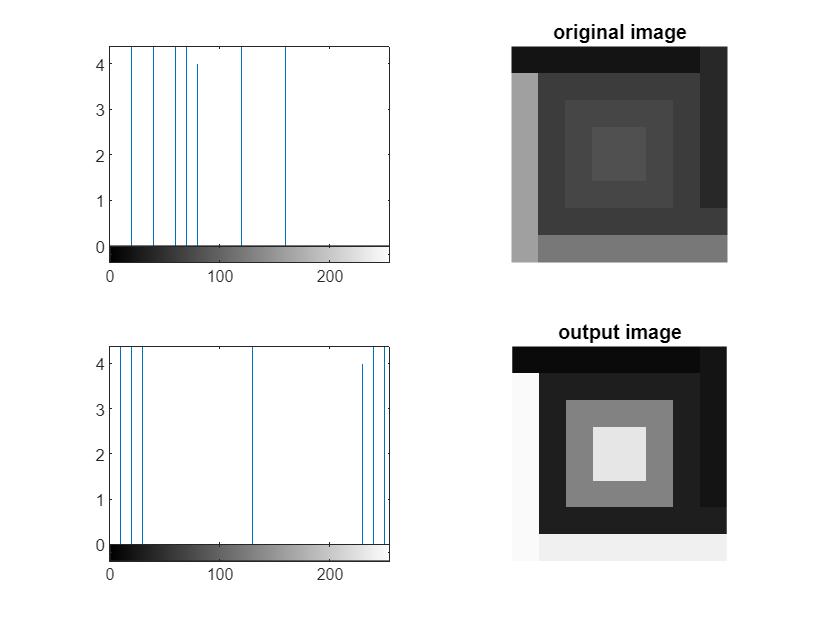

figure 
subplot(2,2,1);imhist(uint8(x),gray(256));
subplot(2,2,2);imshow(uint8(x),gray(256));
title('original image');
subplot(2,2,3);imhist(uint8(y),gray(256));
subplot(2,2,4);imshow(uint8(y),gray(256));
title('output image');

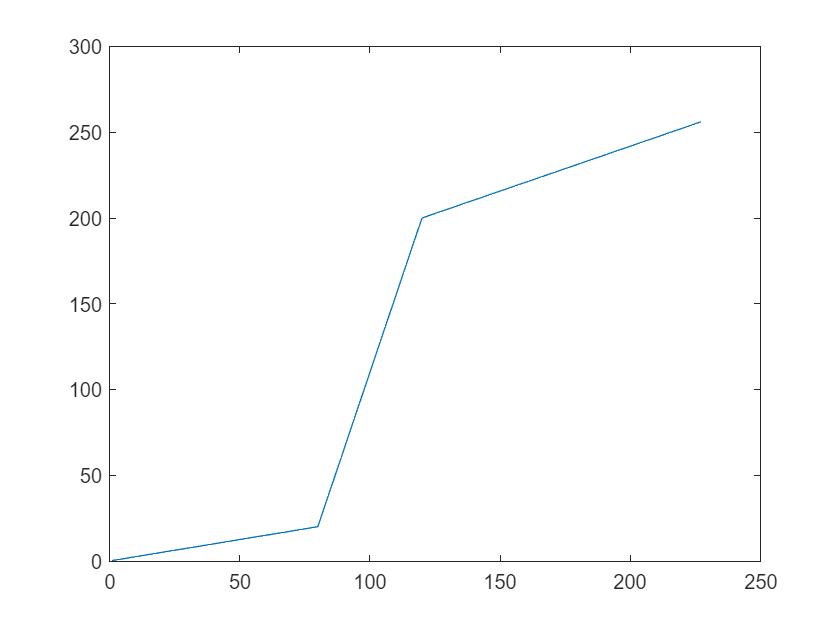



clear
I=imread("cablecar.ppm");
I=rgb2gray(I);
[m,n]=size(I);
for i=1:80
    lut(i)=i/4;
end
for i=80:120
    lut(i)=(180/40)*(i-80)+20;
end
for i=120:227
    lut(i)=(56/107)*(i-120)+200;
end

figure 
plot(lut)

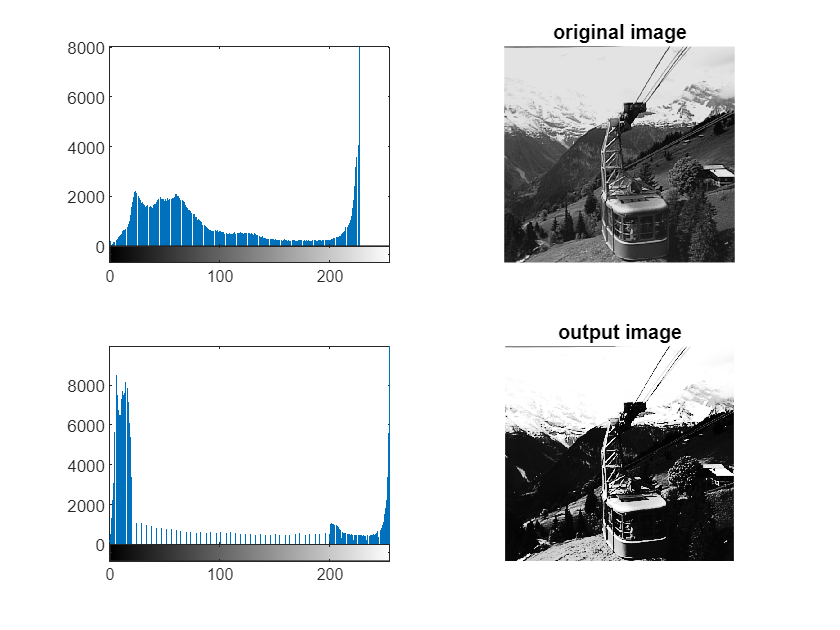


for i=1:m
    for j=1:n
        if I(i,j)==0
            I(i,j)=1;
        elseif I(i,j)>227
            I(i,j)=227;
        end
        
        y(i,j)=(lut((I(i,j))));
    end
end
subplot(2,2,1);imhist(uint8(I),gray(256));
subplot(2,2,2);imshow(uint8(I),gray(256));
title('original image');
subplot(2,2,3);imhist(uint8(y),gray(256));
subplot(2,2,4);imshow(uint8(y),gray(256));
title('output image');